## 1. The Experiment

This experimet is based on [Warren et al. 2016](https://doi.org/10.1109/JPROC.2015.2507180)

The participant was implanted with Utah Slanted Electrode Arrays in the ulnar and median nerves.

The participant was presented with a virtual hand on a screen that performed two gestures.

The paticipant was tasked to mimic the motion of the virtual hand with their amputated limb.

The USEA recorded neural signals from the nerves, and the hand kinematics (i.e. the position over time of its joints) were recorded from the computer program.

## 2. The Dataset

clearvars
load('datasets\training_dataset.mat')

The variable `experiment_data` is a struct that contains two matrices and one variable:

- `experiment_data.hand_kinematics`.- An Nx2 matrix containing the kinematic information of **two joints **of the virtual hand during the experiment.

- `experiment_data.raw_neural_data`: An Nx6 matrix containing a **subset of six USEA channels** during the experiment.

- `experiment_data.sample_rate`.- The sample rate in Hz at which both Kinematics, and Neural Data were recorded.

experiment_ttbl = timetable( experiment_data.hand_kinematics, experiment_data.raw_neural_data, ...
                            'SampleRate', experiment_data.sample_rate, ...
                            'VariableNames', ["Hand Kinematics" "Raw Neural Data"])

experiment_ttbl = 948199×2 timetable
         Time         Hand Kinematics    Raw Neural Data
    ______________    _______________    _______________

    0 sec                 0    0           1×6 single   
    3.3333e-05 sec        0    0           1×6 single   
    6.6667e-05 sec        0    0           1×6 single   
    0.0001 sec            0    0           1×6 single   
    0.00013333 sec        0    0           1×6 single   
    0.00016667 sec        0    0           1×6 single   
    0.0002 sec            0    0           1×6 single   
    0.00023333 sec        0    0           1×6 single   
    0.00026667 sec        0    0           1×6 single   
    0.0003 sec            0    0           1×6 single   
    <s

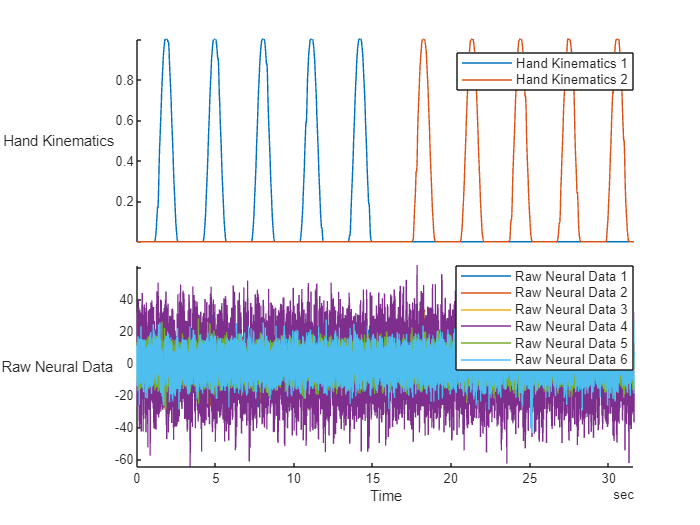

stackedplot(experiment_ttbl)

## 3. The Assignment

The goal of this project is for you to train a Neural Network to map the values of the USEA data to the values of the hand kinematics. In other words, you will train an algorithm to *decode *the desired position of an artificial hand based on the current electrical activity in the remaining limb of the patient.

However, in its current state, the neural data has almost no correlation to the hand kinematics and the neural network won't be able to decode the kinematics. Therefore you have the following tasks: 

- Clean/pre-process the neural data 

- Find/extract features in the neural data that correlate with the kinematics

- Train your neural network using the features from task 2

- Test the performance of your neural network using the testing dataset